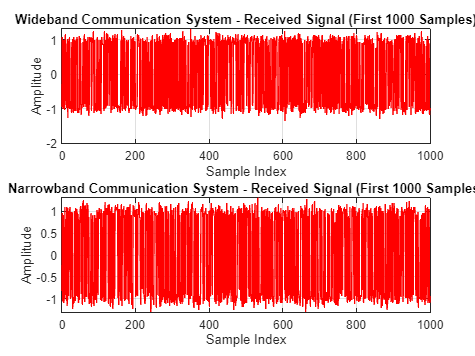

% Common Parameters
numBits = 1e6;            % Number of bits to transmit
EbNo_dB = 0:2:20;         % Eb/No values (in dB)
numObstacles = 5;         % Number of obstacles

% Generate random bits
bits = randi([0, 1], 1, numBits);

% Encoding
encodedBits = bits;  % No encoding for simplicity

% Modulation
modulatedSymbols = 2 * encodedBits - 1;

% BER calculation function
calculateBER = @(receivedBits) sum(bits ~= receivedBits) / numBits;

% Initialize BER vectors
berWideband = zeros(size(EbNo_dB));
berNarrowband = zeros(size(EbNo_dB));

% Wideband Communication System
% Channel Response for Wideband
channelResponseWideband = [1, zeros(1, numObstacles), 1];

% Generate obstacles
obstaclesWideband = randi([0, 1], size(modulatedSymbols)) * 2 - 1;

for i = 1:length(EbNo_dB)
    % Add random noise at each Eb/No value
    noisySymbolsWideband = awgn(modulatedSymbols .* obstaclesWideband, EbNo_dB(i), 'measured');
    
    % Demodulation
    demodulatedSymbolsWideband = noisySymbolsWideband(1:length(modulatedSymbols));
    receivedBitsWideband = demodulatedSymbolsWideband > 0;
    
    % BER calculation for Wideband
    berWideband(i) = calculateBER(receivedBitsWideband);
end

% Narrowband Communication System
% Channel Response for Narrowband
channelResponseNarrowband = [1, ones(1, numObstacles * 10), 1];

% Generate obstacles
obstaclesNarrowband = randi([0, 1], size(modulatedSymbols)) * 2 - 1;

for i = 1:length(EbNo_dB)
    % Add random noise at each Eb/No value
    noisySymbolsNarrowband = awgn(modulatedSymbols .* obstaclesNarrowband, EbNo_dB(i), 'measured');
    
    % Demodulation
    demodulatedSymbolsNarrowband = noisySymbolsNarrowband(1:length(modulatedSymbols));
    receivedBitsNarrowband = demodulatedSymbolsNarrowband > 0;
    
    % BER calculation for Narrowband
    berNarrowband(i) = calculateBER(receivedBitsNarrowband);
end

% Plotting
figure;

% Wideband Communication System
subplot(2, 1, 1);
plot(noisySymbolsWideband(1:1000), 'r');
xlabel('Sample Index');
ylabel('Amplitude');
title('Wideband Communication System - Received Signal (First 1000 Samples)');
grid on;

% Narrowband Communication System
subplot(2, 1, 2);
plot(noisySymbolsNarrowband(1:1000), 'r');
xlabel('Sample Index');
ylabel('Amplitude');
title('Narrowband Communication System - Received Signal (First 1000 Samples)');
grid on;

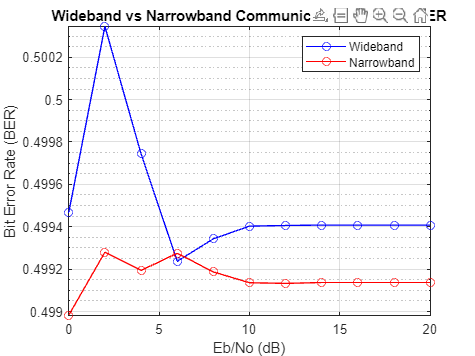


% BER comparison
figure;
semilogy(EbNo_dB, berWideband, 'bo-', 'DisplayName', 'Wideband');
hold on;
semilogy(EbNo_dB, berNarrowband, 'ro-', 'DisplayName', 'Narrowband');
xlabel('Eb/No (dB)');
ylabel('Bit Error Rate (BER)');
title('Wideband vs Narrowband Communication System - BER');
grid on;
legend('Wideband', 'Narrowband');
hold off;